# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                       computeCostMulti.m      ex1data2.txt            lib                     token.mat               
..                      ex1.mlx                 featureNormalize.m      normalEqn.m             warmUpExercise.m        
computeCost.asv         ex1_companion.mlx       gradientDescent.m       plotData.m              
computeCost.m           ex1data1.txt            gradientDescentMulti.m  submit.m                



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

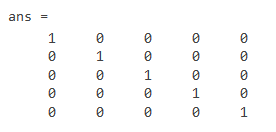

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

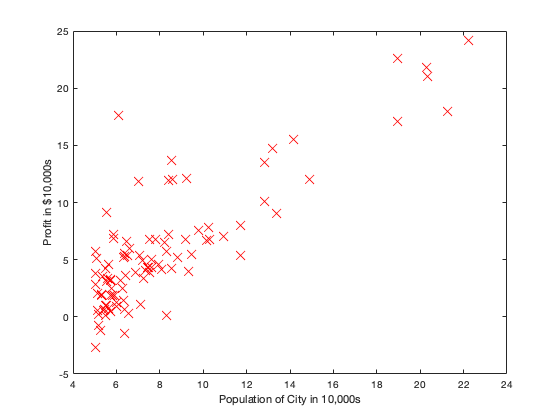

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

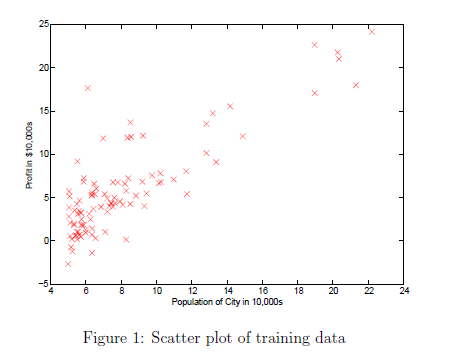

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

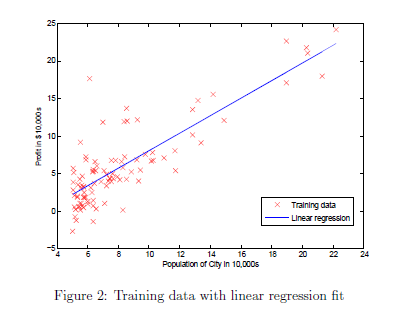    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

temp0 = 0.0584

temp1 = 0.6533

theta =     0.0584
         0


theta =     0.0584
    0.6533


temp0 = 0.0629

temp1 = 0.7700

theta =     0.0629
    0.6533


theta =     0.0629
    0.7700


temp0 = 0.0578

temp1 = 0.7913

theta =     0.0578
    0.7700


theta =     0.0578
    0.7913


temp0 = 0.0511

temp1 = 0.7957

theta =     0.0511
    0.7913


theta =     0.0511
    0.7957


temp0 = 0.0440

temp1 = 0.7971

theta =     0.0440
    0.7957


theta =     0.0440
    0.7971


temp0 = 0.0369

temp1 = 0.7979

theta =     0.0369
    0.7971


theta =     0.0369
    0.7979


temp0 = 0.0298

temp1 = 0.7987

theta =     0.0298
    0.7979


theta =     0.0298
    0.7987


temp0 = 0.0228

temp1 = 0.7994

theta =     0.0228
    0.7987


theta =     0.0228
    0.7994


temp0 = 0.0157

temp1 = 0.8001

theta =     0.0157
    0.7994


theta =     0.0157
    0.8001


temp0 = 0.0086

temp1 = 0.8008

theta =     0.0086
    0.8001


theta =     0.0086
    0.8008


temp0 = 0.0016

temp1 = 0.8015

theta =     0.0016
    0.8008


theta =     0.0016
    0.8015


temp0 = -0.0054

temp1 = 0.8022

theta =    -0.0054
    0.8015


theta =    -0.0054
    0.8022


temp0 = -0.0124

temp1 = 0.8029

theta =    -0.0124
    0.8022


theta =    -0.0124
    0.8029


temp0 = -0.0194

temp1 = 0.8036

theta =    -0.0194
    0.8029


theta =    -0.0194
    0.8036


temp0 = -0.0264

temp1 = 0.8043

theta =    -0.0264
    0.8036


theta =    -0.0264
    0.8043


temp0 = -0.0334

temp1 = 0.8050

theta =    -0.0334
    0.8043


theta =    -0.0334
    0.8050


temp0 = -0.0404

temp1 = 0.8057

theta =    -0.0404
    0.8050


theta =    -0.0404
    0.8057


temp0 = -0.0473

temp1 = 0.8064

theta =    -0.0473
    0.8057


theta =    -0.0473
    0.8064


temp0 = -0.0542

temp1 = 0.8071

theta =    -0.0542
    0.8064


theta =    -0.0542
    0.8071


temp0 = -0.0612

temp1 = 0.8078

theta =    -0.0612
    0.8071


theta =    -0.0612
    0.8078


temp0 = -0.0681

temp1 = 0.8085

theta =    -0.0681
    0.8078


theta =    -0.0681
    0.8085


temp0 = -0.0750

temp1 = 0.8092

theta =    -0.0750
    0.8085


theta =    -0.0750
    0.8092


temp0 = -0.0819

temp1 = 0.8099

theta =    -0.0819
    0.8092


theta =    -0.0819
    0.8099


temp0 = -0.0887

temp1 = 0.8106

theta =    -0.0887
    0.8099


theta =    -0.0887
    0.8106


temp0 = -0.0956

temp1 = 0.8113

theta =    -0.0956
    0.8106


theta =    -0.0956
    0.8113


temp0 = -0.1025

temp1 = 0.8120

theta = 2×1
   -0.1025
    0.8113


theta = 2×1
   -0.1025
    0.8120


temp0 = -0.1093

temp1 = 0.8126

theta = 2×1
   -0.1093
    0.8120


theta = 2×1
   -0.1093
    0.8126


temp0 = -0.1161

temp1 = 0.8133

theta = 2×1
   -0.1161
    0.8126


theta = 2×1
   -0.1161
    0.8133


temp0 = -0.1229

temp1 = 0.8140

theta = 2×1
   -0.1229
    0.8133


theta = 2×1
   -0.1229
    0.8140


temp0 = -0.1297

temp1 = 0.8147

theta = 2×1
   -0.1297
    0.8140


theta = 2×1
   -0.1297
    0.8147


temp0 = -0.1365

temp1 = 0.8154

theta = 2×1
   -0.1365
    0.8147


theta = 2×1
   -0.1365
    0.8154


temp0 = -0.1433

temp1 = 0.8161

theta = 2×1
   -0.1433
    0.8154


theta = 2×1
   -0.1433
    0.8161


temp0 = -0.1501

temp1 = 0.8167

theta = 2×1
   -0.1501
    0.8161


theta = 2×1
   -0.1501
    0.8167


temp0 = -0.1568

temp1 = 0.8174

theta = 2×1
   -0.1568
    0.8167


theta = 2×1
   -0.1568
    0.8174


temp0 = -0.1636

temp1 = 0.8181

theta = 2×1
   -0.1636
    0.8174


theta = 2×1
   -0.1636
    0.8181


temp0 = -0.1703

temp1 = 0.8188

theta = 2×1
   -0.1703
    0.8181


theta = 2×1
   -0.1703
    0.8188


temp0 = -0.1770

temp1 = 0.8194

theta = 2×1
   -0.1770
    0.8188


theta = 2×1
   -0.1770
    0.8194


temp0 = -0.1837

temp1 = 0.8201

theta = 2×1
   -0.1837
    0.8194


theta = 2×1
   -0.1837
    0.8201


temp0 = -0.1904

temp1 = 0.8208

theta = 2×1
   -0.1904
    0.8201


theta = 2×1
   -0.1904
    0.8208


temp0 = -0.1971

temp1 = 0.8215

theta = 2×1
   -0.1971
    0.8208


theta = 2×1
   -0.1971
    0.8215


temp0 = -0.2037

temp1 = 0.8221

theta = 2×1
   -0.2037
    0.8215


theta = 2×1
   -0.2037
    0.8221


temp0 = -0.2104

temp1 = 0.8228

theta = 2×1
   -0.2104
    0.8221


theta = 2×1
   -0.2104
    0.8228


temp0 = -0.2170

temp1 = 0.8235

theta = 2×1
   -0.2170
    0.8228


theta = 2×1
   -0.2170
    0.8235


temp0 = -0.2237

temp1 = 0.8241

theta = 2×1
   -0.2237
    0.8235


theta = 2×1
   -0.2237
    0.8241


temp0 = -0.2303

temp1 = 0.8248

theta = 2×1
   -0.2303
    0.8241


theta = 2×1
   -0.2303
    0.8248


temp0 = -0.2369

temp1 = 0.8255

theta = 2×1
   -0.2369
    0.8248


theta = 2×1
   -0.2369
    0.8255


temp0 = -0.2435

temp1 = 0.8261

theta = 2×1
   -0.2435
    0.8255


theta = 2×1
   -0.2435
    0.8261


temp0 = -0.2501

temp1 = 0.8268

theta = 2×1
   -0.2501
    0.8261


theta = 2×1
   -0.2501
    0.8268


temp0 = -0.2566

temp1 = 0.8274

theta = 2×1
   -0.2566
    0.8268


theta = 2×1
   -0.2566
    0.8274


temp0 = -0.2632

temp1 = 0.8281

theta = 2×1
   -0.2632
    0.8274


theta = 2×1
   -0.2632
    0.8281


temp0 = -0.2698

temp1 = 0.8288

theta = 2×1
   -0.2698
    0.8281


theta = 2×1
   -0.2698
    0.8288


temp0 = -0.2763

temp1 = 0.8294

theta = 2×1
   -0.2763
    0.8288


theta = 2×1
   -0.2763
    0.8294


temp0 = -0.2828

temp1 = 0.8301

theta = 2×1
   -0.2828
    0.8294


theta = 2×1
   -0.2828
    0.8301


temp0 = -0.2893

temp1 = 0.8307

theta = 2×1
   -0.2893
    0.8301


theta = 2×1
   -0.2893
    0.8307


temp0 = -0.2958

temp1 = 0.8314

theta = 2×1
   -0.2958
    0.8307


theta = 2×1
   -0.2958
    0.8314


temp0 = -0.3023

temp1 = 0.8320

theta = 2×1
   -0.3023
    0.8314


theta = 2×1
   -0.3023
    0.8320


temp0 = -0.3088

temp1 = 0.8327

theta = 2×1
   -0.3088
    0.8320


theta = 2×1
   -0.3088
    0.8327


temp0 = -0.3153

temp1 = 0.8333

theta = 2×1
   -0.3153
    0.8327


theta = 2×1
   -0.3153
    0.8333


temp0 = -0.3217

temp1 = 0.8340

theta = 2×1
   -0.3217
    0.8333


theta = 2×1
   -0.3217
    0.8340


temp0 = -0.3282

temp1 = 0.8346

theta = 2×1
   -0.3282
    0.8340


theta = 2×1
   -0.3282
    0.8346


temp0 = -0.3346

temp1 = 0.8353

theta = 2×1
   -0.3346
    0.8346


theta = 2×1
   -0.3346
    0.8353


temp0 = -0.3410

temp1 = 0.8359

theta = 2×1
   -0.3410
    0.8353


theta = 2×1
   -0.3410
    0.8359


temp0 = -0.3474

temp1 = 0.8366

theta = 2×1
   -0.3474
    0.8359


theta = 2×1
   -0.3474
    0.8366


temp0 = -0.3538

temp1 = 0.8372

theta = 2×1
   -0.3538
    0.8366


theta = 2×1
   -0.3538
    0.8372


temp0 = -0.3602

temp1 = 0.8378

theta = 2×1
   -0.3602
    0.8372


theta = 2×1
   -0.3602
    0.8378


temp0 = -0.3666

temp1 = 0.8385

theta = 2×1
   -0.3666
    0.8378


theta = 2×1
   -0.3666
    0.8385


temp0 = -0.3729

temp1 = 0.8391

theta = 2×1
   -0.3729
    0.8385


theta = 2×1
   -0.3729
    0.8391


temp0 = -0.3793

temp1 = 0.8398

theta = 2×1
   -0.3793
    0.8391


theta = 2×1
   -0.3793
    0.8398


temp0 = -0.3856

temp1 = 0.8404

theta = 2×1
   -0.3856
    0.8398


theta = 2×1
   -0.3856
    0.8404


temp0 = -0.3919

temp1 = 0.8410

theta = 2×1
   -0.3919
    0.8404


theta = 2×1
   -0.3919
    0.8410


temp0 = -0.3983

temp1 = 0.8417

theta = 2×1
   -0.3983
    0.8410


theta = 2×1
   -0.3983
    0.8417


temp0 = -0.4046

temp1 = 0.8423

theta = 2×1
   -0.4046
    0.8417


theta = 2×1
   -0.4046
    0.8423


temp0 = -0.4109

temp1 = 0.8429

theta = 2×1
   -0.4109
    0.8423


theta = 2×1
   -0.4109
    0.8429


temp0 = -0.4171

temp1 = 0.8436

theta = 2×1
   -0.4171
    0.8429


theta = 2×1
   -0.4171
    0.8436


temp0 = -0.4234

temp1 = 0.8442

theta = 2×1
   -0.4234
    0.8436


theta = 2×1
   -0.4234
    0.8442


temp0 = -0.4297

temp1 = 0.8448

theta = 2×1
   -0.4297
    0.8442


theta = 2×1
   -0.4297
    0.8448


temp0 = -0.4359

temp1 = 0.8455

theta = 2×1
   -0.4359
    0.8448


theta = 2×1
   -0.4359
    0.8455


temp0 = -0.4422

temp1 = 0.8461

theta = 2×1
   -0.4422
    0.8455


theta = 2×1
   -0.4422
    0.8461


temp0 = -0.4484

temp1 = 0.8467

theta = 2×1
   -0.4484
    0.8461


theta = 2×1
   -0.4484
    0.8467


temp0 = -0.4546

temp1 = 0.8473

theta = 2×1
   -0.4546
    0.8467


theta = 2×1
   -0.4546
    0.8473


temp0 = -0.4608

temp1 = 0.8480

theta = 2×1
   -0.4608
    0.8473


theta = 2×1
   -0.4608
    0.8480


temp0 = -0.4670

temp1 = 0.8486

theta = 2×1
   -0.4670
    0.8480


theta = 2×1
   -0.4670
    0.8486


temp0 = -0.4732

temp1 = 0.8492

theta = 2×1
   -0.4732
    0.8486


theta = 2×1
   -0.4732
    0.8492


temp0 = -0.4793

temp1 = 0.8498

theta = 2×1
   -0.4793
    0.8492


theta = 2×1
   -0.4793
    0.8498


temp0 = -0.4855

temp1 = 0.8504

theta = 2×1
   -0.4855
    0.8498


theta = 2×1
   -0.4855
    0.8504


temp0 = -0.4916

temp1 = 0.8511

theta = 2×1
   -0.4916
    0.8504


theta = 2×1
   -0.4916
    0.8511


temp0 = -0.4978

temp1 = 0.8517

theta = 2×1
   -0.4978
    0.8511


theta = 2×1
   -0.4978
    0.8517


temp0 = -0.5039

temp1 = 0.8523

theta = 2×1
   -0.5039
    0.8517


theta = 2×1
   -0.5039
    0.8523


temp0 = -0.5100

temp1 = 0.8529

theta = 2×1
   -0.5100
    0.8523


theta = 2×1
   -0.5100
    0.8529


temp0 = -0.5161

temp1 = 0.8535

theta = 2×1
   -0.5161
    0.8529


theta = 2×1
   -0.5161
    0.8535


temp0 = -0.5222

temp1 = 0.8541

theta = 2×1
   -0.5222
    0.8535


theta = 2×1
   -0.5222
    0.8541


temp0 = -0.5283

temp1 = 0.8547

theta = 2×1
   -0.5283
    0.8541


theta = 2×1
   -0.5283
    0.8547


temp0 = -0.5344

temp1 = 0.8553

theta = 2×1
   -0.5344
    0.8547


theta = 2×1
   -0.5344
    0.8553


temp0 = -0.5404

temp1 = 0.8560

theta = 2×1
   -0.5404
    0.8553


theta = 2×1
   -0.5404
    0.8560


temp0 = -0.5465

temp1 = 0.8566

theta = 2×1
   -0.5465
    0.8560


theta = 2×1
   -0.5465
    0.8566


temp0 = -0.5525

temp1 = 0.8572

theta = 2×1
   -0.5525
    0.8566


theta = 2×1
   -0.5525
    0.8572


temp0 = -0.5585

temp1 = 0.8578

theta = 2×1
   -0.5585
    0.8572


theta = 2×1
   -0.5585
    0.8578


temp0 = -0.5646

temp1 = 0.8584

theta = 2×1
   -0.5646
    0.8578


theta = 2×1
   -0.5646
    0.8584


temp0 = -0.5706

temp1 = 0.8590

theta = 2×1
   -0.5706
    0.8584


theta = 2×1
   -0.5706
    0.8590


temp0 = -0.5766

temp1 = 0.8596

theta = 2×1
   -0.5766
    0.8590


theta = 2×1
   -0.5766
    0.8596


temp0 = -0.5825

temp1 = 0.8602

theta = 2×1
   -0.5825
    0.8596


theta = 2×1
   -0.5825
    0.8602


temp0 = -0.5885

temp1 = 0.8608

theta = 2×1
   -0.5885
    0.8602


theta = 2×1
   -0.5885
    0.8608


temp0 = -0.5945

temp1 = 0.8614

theta = 2×1
   -0.5945
    0.8608


theta = 2×1
   -0.5945
    0.8614


temp0 = -0.6004

temp1 = 0.8620

theta = 2×1
   -0.6004
    0.8614


theta = 2×1
   -0.6004
    0.8620


temp0 = -0.6064

temp1 = 0.8626

theta = 2×1
   -0.6064
    0.8620


theta = 2×1
   -0.6064
    0.8626


temp0 = -0.6123

temp1 = 0.8632

theta = 2×1
   -0.6123
    0.8626


theta = 2×1
   -0.6123
    0.8632


temp0 = -0.6182

temp1 = 0.8638

theta = 2×1
   -0.6182
    0.8632


theta = 2×1
   -0.6182
    0.8638


temp0 = -0.6241

temp1 = 0.8644

theta = 2×1
   -0.6241
    0.8638


theta = 2×1
   -0.6241
    0.8644


temp0 = -0.6300

temp1 = 0.8650

theta = 2×1
   -0.6300
    0.8644


theta = 2×1
   -0.6300
    0.8650


temp0 = -0.6359

temp1 = 0.8655

theta = 2×1
   -0.6359
    0.8650


theta = 2×1
   -0.6359
    0.8655


temp0 = -0.6418

temp1 = 0.8661

theta = 2×1
   -0.6418
    0.8655


theta = 2×1
   -0.6418
    0.8661


temp0 = -0.6476

temp1 = 0.8667

theta = 2×1
   -0.6476
    0.8661


theta = 2×1
   -0.6476
    0.8667


temp0 = -0.6535

temp1 = 0.8673

theta = 2×1
   -0.6535
    0.8667


theta = 2×1
   -0.6535
    0.8673


temp0 = -0.6593

temp1 = 0.8679

theta = 2×1
   -0.6593
    0.8673


theta = 2×1
   -0.6593
    0.8679


temp0 = -0.6652

temp1 = 0.8685

theta = 2×1
   -0.6652
    0.8679


theta = 2×1
   -0.6652
    0.8685


temp0 = -0.6710

temp1 = 0.8691

theta = 2×1
   -0.6710
    0.8685


theta = 2×1
   -0.6710
    0.8691


temp0 = -0.6768

temp1 = 0.8697

theta = 2×1
   -0.6768
    0.8691


theta = 2×1
   -0.6768
    0.8697


temp0 = -0.6826

temp1 = 0.8702

theta = 2×1
   -0.6826
    0.8697


theta = 2×1
   -0.6826
    0.8702


temp0 = -0.6884

temp1 = 0.8708

theta = 2×1
   -0.6884
    0.8702


theta = 2×1
   -0.6884
    0.8708


temp0 = -0.6942

temp1 = 0.8714

theta = 2×1
   -0.6942
    0.8708


theta = 2×1
   -0.6942
    0.8714


temp0 = -0.7000

temp1 = 0.8720

theta = 2×1
   -0.7000
    0.8714


theta = 2×1
   -0.7000
    0.8720


temp0 = -0.7057

temp1 = 0.8726

theta = 2×1
   -0.7057
    0.8720


theta = 2×1
   -0.7057
    0.8726


temp0 = -0.7115

temp1 = 0.8731

theta = 2×1
   -0.7115
    0.8726


theta = 2×1
   -0.7115
    0.8731


temp0 = -0.7172

temp1 = 0.8737

theta = 2×1
   -0.7172
    0.8731


theta = 2×1
   -0.7172
    0.8737


temp0 = -0.7229

temp1 = 0.8743

theta = 2×1
   -0.7229
    0.8737


theta = 2×1
   -0.7229
    0.8743


temp0 = -0.7287

temp1 = 0.8749

theta = 2×1
   -0.7287
    0.8743


theta = 2×1
   -0.7287
    0.8749


temp0 = -0.7344

temp1 = 0.8754

theta = 2×1
   -0.7344
    0.8749


theta = 2×1
   -0.7344
    0.8754


temp0 = -0.7401

temp1 = 0.8760

theta = 2×1
   -0.7401
    0.8754


theta = 2×1
   -0.7401
    0.8760


temp0 = -0.7458

temp1 = 0.8766

theta = 2×1
   -0.7458
    0.8760


theta = 2×1
   -0.7458
    0.8766


temp0 = -0.7514

temp1 = 0.8772

theta = 2×1
   -0.7514
    0.8766


theta = 2×1
   -0.7514
    0.8772


temp0 = -0.7571

temp1 = 0.8777

theta = 2×1
   -0.7571
    0.8772


theta = 2×1
   -0.7571
    0.8777


temp0 = -0.7628

temp1 = 0.8783

theta = 2×1
   -0.7628
    0.8777


theta = 2×1
   -0.7628
    0.8783


temp0 = -0.7684

temp1 = 0.8789

theta = 2×1
   -0.7684
    0.8783


theta = 2×1
   -0.7684
    0.8789


temp0 = -0.7740

temp1 = 0.8794

theta = 2×1
   -0.7740
    0.8789


theta = 2×1
   -0.7740
    0.8794


temp0 = -0.7797

temp1 = 0.8800

theta = 2×1
   -0.7797
    0.8794


theta = 2×1
   -0.7797
    0.8800


temp0 = -0.7853

temp1 = 0.8806

theta = 2×1
   -0.7853
    0.8800


theta = 2×1
   -0.7853
    0.8806


temp0 = -0.7909

temp1 = 0.8811

theta = 2×1
   -0.7909
    0.8806


theta = 2×1
   -0.7909
    0.8811


temp0 = -0.7965

temp1 = 0.8817

theta = 2×1
   -0.7965
    0.8811


theta = 2×1
   -0.7965
    0.8817


temp0 = -0.8021

temp1 = 0.8822

theta = 2×1
   -0.8021
    0.8817


theta = 2×1
   -0.8021
    0.8822


temp0 = -0.8077

temp1 = 0.8828

theta = 2×1
   -0.8077
    0.8822


theta = 2×1
   -0.8077
    0.8828


temp0 = -0.8132

temp1 = 0.8834

theta = 2×1
   -0.8132
    0.8828


theta = 2×1
   -0.8132
    0.8834


temp0 = -0.8188

temp1 = 0.8839

theta = 2×1
   -0.8188
    0.8834


theta = 2×1
   -0.8188
    0.8839


temp0 = -0.8243

temp1 = 0.8845

theta = 2×1
   -0.8243
    0.8839


theta = 2×1
   -0.8243
    0.8845


temp0 = -0.8299

temp1 = 0.8850

theta = 2×1
   -0.8299
    0.8845


theta = 2×1
   -0.8299
    0.8850


temp0 = -0.8354

temp1 = 0.8856

theta = 2×1
   -0.8354
    0.8850


theta = 2×1
   -0.8354
    0.8856


temp0 = -0.8409

temp1 = 0.8861

theta = 2×1
   -0.8409
    0.8856


theta = 2×1
   -0.8409
    0.8861


temp0 = -0.8464

temp1 = 0.8867

theta = 2×1
   -0.8464
    0.8861


theta = 2×1
   -0.8464
    0.8867


temp0 = -0.8519

temp1 = 0.8872

theta = 2×1
   -0.8519
    0.8867


theta = 2×1
   -0.8519
    0.8872


temp0 = -0.8574

temp1 = 0.8878

theta = 2×1
   -0.8574
    0.8872


theta = 2×1
   -0.8574
    0.8878


temp0 = -0.8629

temp1 = 0.8883

theta = 2×1
   -0.8629
    0.8878


theta = 2×1
   -0.8629
    0.8883


temp0 = -0.8683

temp1 = 0.8889

theta = 2×1
   -0.8683
    0.8883


theta = 2×1
   -0.8683
    0.8889


temp0 = -0.8738

temp1 = 0.8894

theta = 2×1
   -0.8738
    0.8889


theta = 2×1
   -0.8738
    0.8894


temp0 = -0.8793

temp1 = 0.8900

theta = 2×1
   -0.8793
    0.8894


theta = 2×1
   -0.8793
    0.8900


temp0 = -0.8847

temp1 = 0.8905

theta = 2×1
   -0.8847
    0.8900


theta = 2×1
   -0.8847
    0.8905


temp0 = -0.8901

temp1 = 0.8911

theta = 2×1
   -0.8901
    0.8905


theta = 2×1
   -0.8901
    0.8911


temp0 = -0.8955

temp1 = 0.8916

theta = 2×1
   -0.8955
    0.8911


theta = 2×1
   -0.8955
    0.8916


temp0 = -0.9009

temp1 = 0.8922

theta = 2×1
   -0.9009
    0.8916


theta = 2×1
   -0.9009
    0.8922


temp0 = -0.9063

temp1 = 0.8927

theta = 2×1
   -0.9063
    0.8922


theta = 2×1
   -0.9063
    0.8927


temp0 = -0.9117

temp1 = 0.8933

theta = 2×1
   -0.9117
    0.8927


theta = 2×1
   -0.9117
    0.8933


temp0 = -0.9171

temp1 = 0.8938

theta = 2×1
   -0.9171
    0.8933


theta = 2×1
   -0.9171
    0.8938


temp0 = -0.9225

temp1 = 0.8943

theta = 2×1
   -0.9225
    0.8938


theta = 2×1
   -0.9225
    0.8943


temp0 = -0.9278

temp1 = 0.8949

theta = 2×1
   -0.9278
    0.8943


theta = 2×1
   -0.9278
    0.8949


temp0 = -0.9332

temp1 = 0.8954

theta = 2×1
   -0.9332
    0.8949


theta = 2×1
   -0.9332
    0.8954


temp0 = -0.9385

temp1 = 0.8959

theta = 2×1
   -0.9385
    0.8954


theta = 2×1
   -0.9385
    0.8959


temp0 = -0.9439

temp1 = 0.8965

theta = 2×1
   -0.9439
    0.8959


theta = 2×1
   -0.9439
    0.8965


temp0 = -0.9492

temp1 = 0.8970

theta = 2×1
   -0.9492
    0.8965


theta = 2×1
   -0.9492
    0.8970


temp0 = -0.9545

temp1 = 0.8975

theta = 2×1
   -0.9545
    0.8970


theta = 2×1
   -0.9545
    0.8975


temp0 = -0.9598

temp1 = 0.8981

theta = 2×1
   -0.9598
    0.8975


theta = 2×1
   -0.9598
    0.8981


temp0 = -0.9651

temp1 = 0.8986

theta = 2×1
   -0.9651
    0.8981


theta = 2×1
   -0.9651
    0.8986


temp0 = -0.9704

temp1 = 0.8991

theta = 2×1
   -0.9704
    0.8986


theta = 2×1
   -0.9704
    0.8991


temp0 = -0.9756

temp1 = 0.8997

theta = 2×1
   -0.9756
    0.8991


theta = 2×1
   -0.9756
    0.8997


temp0 = -0.9809

temp1 = 0.9002

theta = 2×1
   -0.9809
    0.8997


theta = 2×1
   -0.9809
    0.9002


temp0 = -0.9862

temp1 = 0.9007

theta = 2×1
   -0.9862
    0.9002


theta = 2×1
   -0.9862
    0.9007


temp0 = -0.9914

temp1 = 0.9013

theta = 2×1
   -0.9914
    0.9007


theta = 2×1
   -0.9914
    0.9013


temp0 = -0.9966

temp1 = 0.9018

theta = 2×1
   -0.9966
    0.9013


theta = 2×1
   -0.9966
    0.9018


temp0 = -1.0019

temp1 = 0.9023

theta = 2×1
   -1.0019
    0.9018


theta = 2×1
   -1.0019
    0.9023


temp0 = -1.0071

temp1 = 0.9028

theta = 2×1
   -1.0071
    0.9023


theta = 2×1
   -1.0071
    0.9028


temp0 = -1.0123

temp1 = 0.9034

theta = 2×1
   -1.0123
    0.9028


theta = 2×1
   -1.0123
    0.9034


temp0 = -1.0175

temp1 = 0.9039

theta = 2×1
   -1.0175
    0.9034


theta = 2×1
   -1.0175
    0.9039


temp0 = -1.0227

temp1 = 0.9044

theta = 2×1
   -1.0227
    0.9039


theta = 2×1
   -1.0227
    0.9044


temp0 = -1.0279

temp1 = 0.9049

theta = 2×1
   -1.0279
    0.9044


theta = 2×1
   -1.0279
    0.9049


temp0 = -1.0330

temp1 = 0.9054

theta = 2×1
   -1.0330
    0.9049


theta = 2×1
   -1.0330
    0.9054


temp0 = -1.0382

temp1 = 0.9060

theta = 2×1
   -1.0382
    0.9054


theta = 2×1
   -1.0382
    0.9060


temp0 = -1.0433

temp1 = 0.9065

theta = 2×1
   -1.0433
    0.9060


theta = 2×1
   -1.0433
    0.9065


temp0 = -1.0485

temp1 = 0.9070

theta = 2×1
   -1.0485
    0.9065


theta = 2×1
   -1.0485
    0.9070


temp0 = -1.0536

temp1 = 0.9075

theta = 2×1
   -1.0536
    0.9070


theta = 2×1
   -1.0536
    0.9075


temp0 = -1.0587

temp1 = 0.9080

theta = 2×1
   -1.0587
    0.9075


theta = 2×1
   -1.0587
    0.9080


temp0 = -1.0638

temp1 = 0.9085

theta = 2×1
   -1.0638
    0.9080


theta = 2×1
   -1.0638
    0.9085


temp0 = -1.0690

temp1 = 0.9090

theta = 2×1
   -1.0690
    0.9085


theta = 2×1
   -1.0690
    0.9090


temp0 = -1.0740

temp1 = 0.9096

theta = 2×1
   -1.0740
    0.9090


theta = 2×1
   -1.0740
    0.9096


temp0 = -1.0791

temp1 = 0.9101

theta = 2×1
   -1.0791
    0.9096


theta = 2×1
   -1.0791
    0.9101


temp0 = -1.0842

temp1 = 0.9106

theta = 2×1
   -1.0842
    0.9101


theta = 2×1
   -1.0842
    0.9106


temp0 = -1.0893

temp1 = 0.9111

theta = 2×1
   -1.0893
    0.9106


theta = 2×1
   -1.0893
    0.9111


temp0 = -1.0943

temp1 = 0.9116

theta = 2×1
   -1.0943
    0.9111


theta = 2×1
   -1.0943
    0.9116


temp0 = -1.0994

temp1 = 0.9121

theta = 2×1
   -1.0994
    0.9116


theta = 2×1
   -1.0994
    0.9121


temp0 = -1.1044

temp1 = 0.9126

theta = 2×1
   -1.1044
    0.9121


theta = 2×1
   -1.1044
    0.9126


temp0 = -1.1095

temp1 = 0.9131

theta = 2×1
   -1.1095
    0.9126


theta = 2×1
   -1.1095
    0.9131


temp0 = -1.1145

temp1 = 0.9136

theta = 2×1
   -1.1145
    0.9131


theta = 2×1
   -1.1145
    0.9136


temp0 = -1.1195

temp1 = 0.9141

theta = 2×1
   -1.1195
    0.9136


theta = 2×1
   -1.1195
    0.9141


temp0 = -1.1245

temp1 = 0.9146

theta = 2×1
   -1.1245
    0.9141


theta = 2×1
   -1.1245
    0.9146


temp0 = -1.1295

temp1 = 0.9151

theta = 2×1
   -1.1295
    0.9146


theta = 2×1
   -1.1295
    0.9151


temp0 = -1.1345

temp1 = 0.9156

theta = 2×1
   -1.1345
    0.9151


theta = 2×1
   -1.1345
    0.9156


temp0 = -1.1395

temp1 = 0.9161

theta = 2×1
   -1.1395
    0.9156


theta = 2×1
   -1.1395
    0.9161


temp0 = -1.1444

temp1 = 0.9166

theta = 2×1
   -1.1444
    0.9161


theta = 2×1
   -1.1444
    0.9166


temp0 = -1.1494

temp1 = 0.9171

theta = 2×1
   -1.1494
    0.9166


theta = 2×1
   -1.1494
    0.9171


temp0 = -1.1543

temp1 = 0.9176

theta = 2×1
   -1.1543
    0.9171


theta = 2×1
   -1.1543
    0.9176


temp0 = -1.1593

temp1 = 0.9181

theta = 2×1
   -1.1593
    0.9176


theta = 2×1
   -1.1593
    0.9181


temp0 = -1.1642

temp1 = 0.9186

theta = 2×1
   -1.1642
    0.9181


theta = 2×1
   -1.1642
    0.9186


temp0 = -1.1691

temp1 = 0.9191

theta = 2×1
   -1.1691
    0.9186


theta = 2×1
   -1.1691
    0.9191


temp0 = -1.1741

temp1 = 0.9196

theta = 2×1
   -1.1741
    0.9191


theta = 2×1
   -1.1741
    0.9196


temp0 = -1.1790

temp1 = 0.9201

theta = 2×1
   -1.1790
    0.9196


theta = 2×1
   -1.1790
    0.9201


temp0 = -1.1839

temp1 = 0.9206

theta = 2×1
   -1.1839
    0.9201


theta = 2×1
   -1.1839
    0.9206


temp0 = -1.1887

temp1 = 0.9211

theta = 2×1
   -1.1887
    0.9206


theta = 2×1
   -1.1887
    0.9211


temp0 = -1.1936

temp1 = 0.9216

theta = 2×1
   -1.1936
    0.9211


theta = 2×1
   -1.1936
    0.9216


temp0 = -1.1985

temp1 = 0.9221

theta = 2×1
   -1.1985
    0.9216


theta = 2×1
   -1.1985
    0.9221


temp0 = -1.2034

temp1 = 0.9226

theta = 2×1
   -1.2034
    0.9221


theta = 2×1
   -1.2034
    0.9226


temp0 = -1.2082

temp1 = 0.9230

theta = 2×1
   -1.2082
    0.9226


theta = 2×1
   -1.2082
    0.9230


temp0 = -1.2131

temp1 = 0.9235

theta = 2×1
   -1.2131
    0.9230


theta = 2×1
   -1.2131
    0.9235


temp0 = -1.2179

temp1 = 0.9240

theta = 2×1
   -1.2179
    0.9235


theta = 2×1
   -1.2179
    0.9240


temp0 = -1.2227

temp1 = 0.9245

theta = 2×1
   -1.2227
    0.9240


theta = 2×1
   -1.2227
    0.9245


temp0 = -1.2275

temp1 = 0.9250

theta = 2×1
   -1.2275
    0.9245


theta = 2×1
   -1.2275
    0.9250


temp0 = -1.2323

temp1 = 0.9255

theta = 2×1
   -1.2323
    0.9250


theta = 2×1
   -1.2323
    0.9255


temp0 = -1.2371

temp1 = 0.9259

theta = 2×1
   -1.2371
    0.9255


theta = 2×1
   -1.2371
    0.9259


temp0 = -1.2419

temp1 = 0.9264

theta = 2×1
   -1.2419
    0.9259


theta = 2×1
   -1.2419
    0.9264


temp0 = -1.2467

temp1 = 0.9269

theta = 2×1
   -1.2467
    0.9264


theta = 2×1
   -1.2467
    0.9269


temp0 = -1.2515

temp1 = 0.9274

theta = 2×1
   -1.2515
    0.9269


theta = 2×1
   -1.2515
    0.9274


temp0 = -1.2563

temp1 = 0.9279

theta = 2×1
   -1.2563
    0.9274


theta = 2×1
   -1.2563
    0.9279


temp0 = -1.2610

temp1 = 0.9283

theta = 2×1
   -1.2610
    0.9279


theta = 2×1
   -1.2610
    0.9283


temp0 = -1.2658

temp1 = 0.9288

theta = 2×1
   -1.2658
    0.9283


theta = 2×1
   -1.2658
    0.9288


temp0 = -1.2705

temp1 = 0.9293

theta = 2×1
   -1.2705
    0.9288


theta = 2×1
   -1.2705
    0.9293


temp0 = -1.2752

temp1 = 0.9298

theta = 2×1
   -1.2752
    0.9293


theta = 2×1
   -1.2752
    0.9298


temp0 = -1.2800

temp1 = 0.9302

theta = 2×1
   -1.2800
    0.9298


theta = 2×1
   -1.2800
    0.9302


temp0 = -1.2847

temp1 = 0.9307

theta = 2×1
   -1.2847
    0.9302


theta = 2×1
   -1.2847
    0.9307


temp0 = -1.2894

temp1 = 0.9312

theta = 2×1
   -1.2894
    0.9307


theta = 2×1
   -1.2894
    0.9312


temp0 = -1.2941

temp1 = 0.9317

theta = 2×1
   -1.2941
    0.9312


theta = 2×1
   -1.2941
    0.9317


temp0 = -1.2988

temp1 = 0.9321

theta = 2×1
   -1.2988
    0.9317


theta = 2×1
   -1.2988
    0.9321


temp0 = -1.3035

temp1 = 0.9326

theta = 2×1
   -1.3035
    0.9321


theta = 2×1
   -1.3035
    0.9326


temp0 = -1.3081

temp1 = 0.9331

theta = 2×1
   -1.3081
    0.9326


theta = 2×1
   -1.3081
    0.9331


temp0 = -1.3128

temp1 = 0.9335

theta = 2×1
   -1.3128
    0.9331


theta = 2×1
   -1.3128
    0.9335


temp0 = -1.3175

temp1 = 0.9340

theta = 2×1
   -1.3175
    0.9335


theta = 2×1
   -1.3175
    0.9340


temp0 = -1.3221

temp1 = 0.9345

theta = 2×1
   -1.3221
    0.9340


theta = 2×1
   -1.3221
    0.9345


temp0 = -1.3267

temp1 = 0.9349

theta = 2×1
   -1.3267
    0.9345


theta = 2×1
   -1.3267
    0.9349


temp0 = -1.3314

temp1 = 0.9354

theta = 2×1
   -1.3314
    0.9349


theta = 2×1
   -1.3314
    0.9354


temp0 = -1.3360

temp1 = 0.9359

theta = 2×1
   -1.3360
    0.9354


theta = 2×1
   -1.3360
    0.9359


temp0 = -1.3406

temp1 = 0.9363

theta = 2×1
   -1.3406
    0.9359


theta = 2×1
   -1.3406
    0.9363


temp0 = -1.3452

temp1 = 0.9368

theta = 2×1
   -1.3452
    0.9363


theta = 2×1
   -1.3452
    0.9368


temp0 = -1.3498

temp1 = 0.9373

theta = 2×1
   -1.3498
    0.9368


theta = 2×1
   -1.3498
    0.9373


temp0 = -1.3544

temp1 = 0.9377

theta = 2×1
   -1.3544
    0.9373


theta = 2×1
   -1.3544
    0.9377


temp0 = -1.3590

temp1 = 0.9382

theta = 2×1
   -1.3590
    0.9377


theta = 2×1
   -1.3590
    0.9382


temp0 = -1.3636

temp1 = 0.9386

theta = 2×1
   -1.3636
    0.9382


theta = 2×1
   -1.3636
    0.9386


temp0 = -1.3681

temp1 = 0.9391

theta = 2×1
   -1.3681
    0.9386


theta = 2×1
   -1.3681
    0.9391


temp0 = -1.3727

temp1 = 0.9396

theta = 2×1
   -1.3727
    0.9391


theta = 2×1
   -1.3727
    0.9396


temp0 = -1.3772

temp1 = 0.9400

theta = 2×1
   -1.3772
    0.9396


theta = 2×1
   -1.3772
    0.9400


temp0 = -1.3818

temp1 = 0.9405

theta = 2×1
   -1.3818
    0.9400


theta = 2×1
   -1.3818
    0.9405


temp0 = -1.3863

temp1 = 0.9409

theta = 2×1
   -1.3863
    0.9405


theta = 2×1
   -1.3863
    0.9409


temp0 = -1.3908

temp1 = 0.9414

theta = 2×1
   -1.3908
    0.9409


theta = 2×1
   -1.3908
    0.9414


temp0 = -1.3953

temp1 = 0.9418

theta = 2×1
   -1.3953
    0.9414


theta = 2×1
   -1.3953
    0.9418


temp0 = -1.3998

temp1 = 0.9423

theta = 2×1
   -1.3998
    0.9418


theta = 2×1
   -1.3998
    0.9423


temp0 = -1.4043

temp1 = 0.9427

theta = 2×1
   -1.4043
    0.9423


theta = 2×1
   -1.4043
    0.9427


temp0 = -1.4088

temp1 = 0.9432

theta = 2×1
   -1.4088
    0.9427


theta = 2×1
   -1.4088
    0.9432


temp0 = -1.4133

temp1 = 0.9436

theta = 2×1
   -1.4133
    0.9432


theta = 2×1
   -1.4133
    0.9436


temp0 = -1.4178

temp1 = 0.9441

theta = 2×1
   -1.4178
    0.9436


theta = 2×1
   -1.4178
    0.9441


temp0 = -1.4223

temp1 = 0.9445

theta = 2×1
   -1.4223
    0.9441


theta = 2×1
   -1.4223
    0.9445


temp0 = -1.4267

temp1 = 0.9450

theta = 2×1
   -1.4267
    0.9445


theta = 2×1
   -1.4267
    0.9450


temp0 = -1.4312

temp1 = 0.9454

theta = 2×1
   -1.4312
    0.9450


theta = 2×1
   -1.4312
    0.9454


temp0 = -1.4356

temp1 = 0.9459

theta = 2×1
   -1.4356
    0.9454


theta = 2×1
   -1.4356
    0.9459


temp0 = -1.4400

temp1 = 0.9463

theta = 2×1
   -1.4400
    0.9459


theta = 2×1
   -1.4400
    0.9463


temp0 = -1.4445

temp1 = 0.9468

theta = 2×1
   -1.4445
    0.9463


theta = 2×1
   -1.4445
    0.9468


temp0 = -1.4489

temp1 = 0.9472

theta = 2×1
   -1.4489
    0.9468


theta = 2×1
   -1.4489
    0.9472


temp0 = -1.4533

temp1 = 0.9477

theta = 2×1
   -1.4533
    0.9472


theta = 2×1
   -1.4533
    0.9477


temp0 = -1.4577

temp1 = 0.9481

theta = 2×1
   -1.4577
    0.9477


theta = 2×1
   -1.4577
    0.9481


temp0 = -1.4621

temp1 = 0.9485

theta = 2×1
   -1.4621
    0.9481


theta = 2×1
   -1.4621
    0.9485


temp0 = -1.4665

temp1 = 0.9490

theta = 2×1
   -1.4665
    0.9485


theta = 2×1
   -1.4665
    0.9490


temp0 = -1.4709

temp1 = 0.9494

theta = 2×1
   -1.4709
    0.9490


theta = 2×1
   -1.4709
    0.9494


temp0 = -1.4752

temp1 = 0.9499

theta = 2×1
   -1.4752
    0.9494


theta = 2×1
   -1.4752
    0.9499


temp0 = -1.4796

temp1 = 0.9503

theta = 2×1
   -1.4796
    0.9499


theta = 2×1
   -1.4796
    0.9503


temp0 = -1.4840

temp1 = 0.9507

theta = 2×1
   -1.4840
    0.9503


theta = 2×1
   -1.4840
    0.9507


temp0 = -1.4883

temp1 = 0.9512

theta = 2×1
   -1.4883
    0.9507


theta = 2×1
   -1.4883
    0.9512


temp0 = -1.4926

temp1 = 0.9516

theta = 2×1
   -1.4926
    0.9512


theta = 2×1
   -1.4926
    0.9516


temp0 = -1.4970

temp1 = 0.9520

theta = 2×1
   -1.4970
    0.9516


theta = 2×1
   -1.4970
    0.9520


temp0 = -1.5013

temp1 = 0.9525

theta = 2×1
   -1.5013
    0.9520


theta = 2×1
   -1.5013
    0.9525


temp0 = -1.5056

temp1 = 0.9529

theta = 2×1
   -1.5056
    0.9525


theta = 2×1
   -1.5056
    0.9529


temp0 = -1.5099

temp1 = 0.9533

theta = 2×1
   -1.5099
    0.9529


theta = 2×1
   -1.5099
    0.9533


temp0 = -1.5142

temp1 = 0.9538

theta = 2×1
   -1.5142
    0.9533


theta = 2×1
   -1.5142
    0.9538


temp0 = -1.5185

temp1 = 0.9542

theta = 2×1
   -1.5185
    0.9538


theta = 2×1
   -1.5185
    0.9542


temp0 = -1.5228

temp1 = 0.9546

theta = 2×1
   -1.5228
    0.9542


theta = 2×1
   -1.5228
    0.9546


temp0 = -1.5271

temp1 = 0.9551

theta = 2×1
   -1.5271
    0.9546


theta = 2×1
   -1.5271
    0.9551


temp0 = -1.5313

temp1 = 0.9555

theta = 2×1
   -1.5313
    0.9551


theta = 2×1
   -1.5313
    0.9555


temp0 = -1.5356

temp1 = 0.9559

theta = 2×1
   -1.5356
    0.9555


theta = 2×1
   -1.5356
    0.9559


temp0 = -1.5399

temp1 = 0.9564

theta = 2×1
   -1.5399
    0.9559


theta = 2×1
   -1.5399
    0.9564


temp0 = -1.5441

temp1 = 0.9568

theta = 2×1
   -1.5441
    0.9564


theta = 2×1
   -1.5441
    0.9568


temp0 = -1.5484

temp1 = 0.9572

theta = 2×1
   -1.5484
    0.9568


theta = 2×1
   -1.5484
    0.9572


temp0 = -1.5526

temp1 = 0.9576

theta = 2×1
   -1.5526
    0.9572


theta = 2×1
   -1.5526
    0.9576


temp0 = -1.5568

temp1 = 0.9581

theta = 2×1
   -1.5568
    0.9576


theta = 2×1
   -1.5568
    0.9581


temp0 = -1.5610

temp1 = 0.9585

theta = 2×1
   -1.5610
    0.9581


theta = 2×1
   -1.5610
    0.9585


temp0 = -1.5652

temp1 = 0.9589

theta = 2×1
   -1.5652
    0.9585


theta = 2×1
   -1.5652
    0.9589


temp0 = -1.5694

temp1 = 0.9593

theta = 2×1
   -1.5694
    0.9589


theta = 2×1
   -1.5694
    0.9593


temp0 = -1.5736

temp1 = 0.9597

theta = 2×1
   -1.5736
    0.9593


theta = 2×1
   -1.5736
    0.9597


temp0 = -1.5778

temp1 = 0.9602

theta = 2×1
   -1.5778
    0.9597


theta = 2×1
   -1.5778
    0.9602


temp0 = -1.5820

temp1 = 0.9606

theta = 2×1
   -1.5820
    0.9602


theta = 2×1
   -1.5820
    0.9606


temp0 = -1.5862

temp1 = 0.9610

theta = 2×1
   -1.5862
    0.9606


theta = 2×1
   -1.5862
    0.9610


temp0 = -1.5903

temp1 = 0.9614

theta = 2×1
   -1.5903
    0.9610


theta = 2×1
   -1.5903
    0.9614


temp0 = -1.5945

temp1 = 0.9618

theta = 2×1
   -1.5945
    0.9614


theta = 2×1
   -1.5945
    0.9618


temp0 = -1.5986

temp1 = 0.9623

theta = 2×1
   -1.5986
    0.9618


theta = 2×1
   -1.5986
    0.9623


temp0 = -1.6028

temp1 = 0.9627

theta = 2×1
   -1.6028
    0.9623


theta = 2×1
   -1.6028
    0.9627


temp0 = -1.6069

temp1 = 0.9631

theta = 2×1
   -1.6069
    0.9627


theta = 2×1
   -1.6069
    0.9631


temp0 = -1.6110

temp1 = 0.9635

theta = 2×1
   -1.6110
    0.9631


theta = 2×1
   -1.6110
    0.9635


temp0 = -1.6151

temp1 = 0.9639

theta = 2×1
   -1.6151
    0.9635


theta = 2×1
   -1.6151
    0.9639


temp0 = -1.6193

temp1 = 0.9643

theta = 2×1
   -1.6193
    0.9639


theta = 2×1
   -1.6193
    0.9643


temp0 = -1.6234

temp1 = 0.9647

theta = 2×1
   -1.6234
    0.9643


theta = 2×1
   -1.6234
    0.9647


temp0 = -1.6275

temp1 = 0.9652

theta = 2×1
   -1.6275
    0.9647


theta = 2×1
   -1.6275
    0.9652


temp0 = -1.6315

temp1 = 0.9656

theta = 2×1
   -1.6315
    0.9652


theta = 2×1
   -1.6315
    0.9656


temp0 = -1.6356

temp1 = 0.9660

theta = 2×1
   -1.6356
    0.9656


theta = 2×1
   -1.6356
    0.9660


temp0 = -1.6397

temp1 = 0.9664

theta = 2×1
   -1.6397
    0.9660


theta = 2×1
   -1.6397
    0.9664


temp0 = -1.6438

temp1 = 0.9668

theta = 2×1
   -1.6438
    0.9664


theta = 2×1
   -1.6438
    0.9668


temp0 = -1.6478

temp1 = 0.9672

theta = 2×1
   -1.6478
    0.9668


theta = 2×1
   -1.6478
    0.9672


temp0 = -1.6519

temp1 = 0.9676

theta = 2×1
   -1.6519
    0.9672


theta = 2×1
   -1.6519
    0.9676


temp0 = -1.6559

temp1 = 0.9680

theta = 2×1
   -1.6559
    0.9676


theta = 2×1
   -1.6559
    0.9680


temp0 = -1.6600

temp1 = 0.9684

theta = 2×1
   -1.6600
    0.9680


theta = 2×1
   -1.6600
    0.9684


temp0 = -1.6640

temp1 = 0.9688

theta = 2×1
   -1.6640
    0.9684


theta = 2×1
   -1.6640
    0.9688


temp0 = -1.6680

temp1 = 0.9692

theta = 2×1
   -1.6680
    0.9688


theta = 2×1
   -1.6680
    0.9692


temp0 = -1.6720

temp1 = 0.9696

theta = 2×1
   -1.6720
    0.9692


theta = 2×1
   -1.6720
    0.9696


temp0 = -1.6760

temp1 = 0.9700

theta = 2×1
   -1.6760
    0.9696


theta = 2×1
   -1.6760
    0.9700


temp0 = -1.6800

temp1 = 0.9704

theta = 2×1
   -1.6800
    0.9700


theta = 2×1
   -1.6800
    0.9704


temp0 = -1.6840

temp1 = 0.9708

theta = 2×1
   -1.6840
    0.9704


theta = 2×1
   -1.6840
    0.9708


temp0 = -1.6880

temp1 = 0.9712

theta = 2×1
   -1.6880
    0.9708


theta = 2×1
   -1.6880
    0.9712


temp0 = -1.6920

temp1 = 0.9716

theta = 2×1
   -1.6920
    0.9712


theta = 2×1
   -1.6920
    0.9716


temp0 = -1.6960

temp1 = 0.9720

theta = 2×1
   -1.6960
    0.9716


theta = 2×1
   -1.6960
    0.9720


temp0 = -1.6999

temp1 = 0.9724

theta = 2×1
   -1.6999
    0.9720


theta = 2×1
   -1.6999
    0.9724


temp0 = -1.7039

temp1 = 0.9728

theta = 2×1
   -1.7039
    0.9724


theta = 2×1
   -1.7039
    0.9728


temp0 = -1.7079

temp1 = 0.9732

theta = 2×1
   -1.7079
    0.9728


theta = 2×1
   -1.7079
    0.9732


temp0 = -1.7118

temp1 = 0.9736

theta = 2×1
   -1.7118
    0.9732


theta = 2×1
   -1.7118
    0.9736


temp0 = -1.7157

temp1 = 0.9740

theta = 2×1
   -1.7157
    0.9736


theta = 2×1
   -1.7157
    0.9740


temp0 = -1.7197

temp1 = 0.9744

theta = 2×1
   -1.7197
    0.9740


theta = 2×1
   -1.7197
    0.9744


temp0 = -1.7236

temp1 = 0.9748

theta = 2×1
   -1.7236
    0.9744


theta = 2×1
   -1.7236
    0.9748


temp0 = -1.7275

temp1 = 0.9752

theta = 2×1
   -1.7275
    0.9748


theta = 2×1
   -1.7275
    0.9752


temp0 = -1.7314

temp1 = 0.9756

theta = 2×1
   -1.7314
    0.9752


theta = 2×1
   -1.7314
    0.9756


temp0 = -1.7353

temp1 = 0.9760

theta = 2×1
   -1.7353
    0.9756


theta = 2×1
   -1.7353
    0.9760


temp0 = -1.7392

temp1 = 0.9764

theta = 2×1
   -1.7392
    0.9760


theta = 2×1
   -1.7392
    0.9764


temp0 = -1.7431

temp1 = 0.9768

theta = 2×1
   -1.7431
    0.9764


theta = 2×1
   -1.7431
    0.9768


temp0 = -1.7470

temp1 = 0.9772

theta = 2×1
   -1.7470
    0.9768


theta = 2×1
   -1.7470
    0.9772


temp0 = -1.7508

temp1 = 0.9776

theta = 2×1
   -1.7508
    0.9772


theta = 2×1
   -1.7508
    0.9776


temp0 = -1.7547

temp1 = 0.9779

theta = 2×1
   -1.7547
    0.9776


theta = 2×1
   -1.7547
    0.9779


temp0 = -1.7586

temp1 = 0.9783

theta = 2×1
   -1.7586
    0.9779


theta = 2×1
   -1.7586
    0.9783


temp0 = -1.7624

temp1 = 0.9787

theta = 2×1
   -1.7624
    0.9783


theta = 2×1
   -1.7624
    0.9787


temp0 = -1.7663

temp1 = 0.9791

theta = 2×1
   -1.7663
    0.9787


theta = 2×1
   -1.7663
    0.9791


temp0 = -1.7701

temp1 = 0.9795

theta = 2×1
   -1.7701
    0.9791


theta = 2×1
   -1.7701
    0.9795


temp0 = -1.7739

temp1 = 0.9799

theta = 2×1
   -1.7739
    0.9795


theta = 2×1
   -1.7739
    0.9799


temp0 = -1.7778

temp1 = 0.9803

theta = 2×1
   -1.7778
    0.9799


theta = 2×1
   -1.7778
    0.9803


temp0 = -1.7816

temp1 = 0.9806

theta = 2×1
   -1.7816
    0.9803


theta = 2×1
   -1.7816
    0.9806


temp0 = -1.7854

temp1 = 0.9810

theta = 2×1
   -1.7854
    0.9806


theta = 2×1
   -1.7854
    0.9810


temp0 = -1.7892

temp1 = 0.9814

theta = 2×1
   -1.7892
    0.9810


theta = 2×1
   -1.7892
    0.9814


temp0 = -1.7930

temp1 = 0.9818

theta = 2×1
   -1.7930
    0.9814


theta = 2×1
   -1.7930
    0.9818


temp0 = -1.7968

temp1 = 0.9822

theta = 2×1
   -1.7968
    0.9818


theta = 2×1
   -1.7968
    0.9822


temp0 = -1.8006

temp1 = 0.9825

theta = 2×1
   -1.8006
    0.9822


theta = 2×1
   -1.8006
    0.9825


temp0 = -1.8043

temp1 = 0.9829

theta = 2×1
   -1.8043
    0.9825


theta = 2×1
   -1.8043
    0.9829


temp0 = -1.8081

temp1 = 0.9833

theta = 2×1
   -1.8081
    0.9829


theta = 2×1
   -1.8081
    0.9833


temp0 = -1.8119

temp1 = 0.9837

theta = 2×1
   -1.8119
    0.9833


theta = 2×1
   -1.8119
    0.9837


temp0 = -1.8156

temp1 = 0.9841

theta = 2×1
   -1.8156
    0.9837


theta = 2×1
   -1.8156
    0.9841


temp0 = -1.8194

temp1 = 0.9844

theta = 2×1
   -1.8194
    0.9841


theta = 2×1
   -1.8194
    0.9844


temp0 = -1.8231

temp1 = 0.9848

theta = 2×1
   -1.8231
    0.9844


theta = 2×1
   -1.8231
    0.9848


temp0 = -1.8269

temp1 = 0.9852

theta = 2×1
   -1.8269
    0.9848


theta = 2×1
   -1.8269
    0.9852


temp0 = -1.8306

temp1 = 0.9856

theta = 2×1
   -1.8306
    0.9852


theta = 2×1
   -1.8306
    0.9856


temp0 = -1.8343

temp1 = 0.9859

theta = 2×1
   -1.8343
    0.9856


theta = 2×1
   -1.8343
    0.9859


temp0 = -1.8380

temp1 = 0.9863

theta = 2×1
   -1.8380
    0.9859


theta = 2×1
   -1.8380
    0.9863


temp0 = -1.8417

temp1 = 0.9867

theta = 2×1
   -1.8417
    0.9863


theta = 2×1
   -1.8417
    0.9867


temp0 = -1.8454

temp1 = 0.9871

theta = 2×1
   -1.8454
    0.9867


theta = 2×1
   -1.8454
    0.9871


temp0 = -1.8491

temp1 = 0.9874

theta = 2×1
   -1.8491
    0.9871


theta = 2×1
   -1.8491
    0.9874


temp0 = -1.8528

temp1 = 0.9878

theta = 2×1
   -1.8528
    0.9874


theta = 2×1
   -1.8528
    0.9878


temp0 = -1.8565

temp1 = 0.9882

theta = 2×1
   -1.8565
    0.9878


theta = 2×1
   -1.8565
    0.9882


temp0 = -1.8602

temp1 = 0.9885

theta = 2×1
   -1.8602
    0.9882


theta = 2×1
   -1.8602
    0.9885


temp0 = -1.8639

temp1 = 0.9889

theta = 2×1
   -1.8639
    0.9885


theta = 2×1
   -1.8639
    0.9889


temp0 = -1.8675

temp1 = 0.9893

theta = 2×1
   -1.8675
    0.9889


theta = 2×1
   -1.8675
    0.9893


temp0 = -1.8712

temp1 = 0.9896

theta = 2×1
   -1.8712
    0.9893


theta = 2×1
   -1.8712
    0.9896


temp0 = -1.8748

temp1 = 0.9900

theta = 2×1
   -1.8748
    0.9896


theta = 2×1
   -1.8748
    0.9900


temp0 = -1.8785

temp1 = 0.9904

theta = 2×1
   -1.8785
    0.9900


theta = 2×1
   -1.8785
    0.9904


temp0 = -1.8821

temp1 = 0.9907

theta = 2×1
   -1.8821
    0.9904


theta = 2×1
   -1.8821
    0.9907


temp0 = -1.8857

temp1 = 0.9911

theta = 2×1
   -1.8857
    0.9907


theta = 2×1
   -1.8857
    0.9911


temp0 = -1.8894

temp1 = 0.9915

theta = 2×1
   -1.8894
    0.9911


theta = 2×1
   -1.8894
    0.9915


temp0 = -1.8930

temp1 = 0.9918

theta = 2×1
   -1.8930
    0.9915


theta = 2×1
   -1.8930
    0.9918


temp0 = -1.8966

temp1 = 0.9922

theta = 2×1
   -1.8966
    0.9918


theta = 2×1
   -1.8966
    0.9922


temp0 = -1.9002

temp1 = 0.9926

theta = 2×1
   -1.9002
    0.9922


theta = 2×1
   -1.9002
    0.9926


temp0 = -1.9038

temp1 = 0.9929

theta = 2×1
   -1.9038
    0.9926


theta = 2×1
   -1.9038
    0.9929


temp0 = -1.9074

temp1 = 0.9933

theta = 2×1
   -1.9074
    0.9929


theta = 2×1
   -1.9074
    0.9933


temp0 = -1.9110

temp1 = 0.9936

theta = 2×1
   -1.9110
    0.9933


theta = 2×1
   -1.9110
    0.9936


temp0 = -1.9145

temp1 = 0.9940

theta = 2×1
   -1.9145
    0.9936


theta = 2×1
   -1.9145
    0.9940


temp0 = -1.9181

temp1 = 0.9944

theta = 2×1
   -1.9181
    0.9940


theta = 2×1
   -1.9181
    0.9944


temp0 = -1.9217

temp1 = 0.9947

theta = 2×1
   -1.9217
    0.9944


theta = 2×1
   -1.9217
    0.9947


temp0 = -1.9252

temp1 = 0.9951

theta = 2×1
   -1.9252
    0.9947


theta = 2×1
   -1.9252
    0.9951


temp0 = -1.9288

temp1 = 0.9954

theta = 2×1
   -1.9288
    0.9951


theta = 2×1
   -1.9288
    0.9954


temp0 = -1.9323

temp1 = 0.9958

theta = 2×1
   -1.9323
    0.9954


theta = 2×1
   -1.9323
    0.9958


temp0 = -1.9359

temp1 = 0.9961

theta = 2×1
   -1.9359
    0.9958


theta = 2×1
   -1.9359
    0.9961


temp0 = -1.9394

temp1 = 0.9965

theta = 2×1
   -1.9394
    0.9961


theta = 2×1
   -1.9394
    0.9965


temp0 = -1.9429

temp1 = 0.9968

theta = 2×1
   -1.9429
    0.9965


theta = 2×1
   -1.9429
    0.9968


temp0 = -1.9465

temp1 = 0.9972

theta = 2×1
   -1.9465
    0.9968


theta = 2×1
   -1.9465
    0.9972


temp0 = -1.9500

temp1 = 0.9976

theta = 2×1
   -1.9500
    0.9972


theta = 2×1
   -1.9500
    0.9976


temp0 = -1.9535

temp1 = 0.9979

theta = 2×1
   -1.9535
    0.9976


theta = 2×1
   -1.9535
    0.9979


temp0 = -1.9570

temp1 = 0.9983

theta = 2×1
   -1.9570
    0.9979


theta = 2×1
   -1.9570
    0.9983


temp0 = -1.9605

temp1 = 0.9986

theta = 2×1
   -1.9605
    0.9983


theta = 2×1
   -1.9605
    0.9986


temp0 = -1.9640

temp1 = 0.9990

theta = 2×1
   -1.9640
    0.9986


theta = 2×1
   -1.9640
    0.9990


temp0 = -1.9674

temp1 = 0.9993

theta = 2×1
   -1.9674
    0.9990


theta = 2×1
   -1.9674
    0.9993


temp0 = -1.9709

temp1 = 0.9997

theta = 2×1
   -1.9709
    0.9993


theta = 2×1
   -1.9709
    0.9997


temp0 = -1.9744

temp1 = 1.0000

theta = 2×1
   -1.9744
    0.9997


theta = 2×1
   -1.9744
    1.0000


temp0 = -1.9778

temp1 = 1.0004

theta = 2×1
   -1.9778
    1.0000


theta = 2×1
   -1.9778
    1.0004


temp0 = -1.9813

temp1 = 1.0007

theta = 2×1
   -1.9813
    1.0004


theta = 2×1
   -1.9813
    1.0007


temp0 = -1.9848

temp1 = 1.0011

theta = 2×1
   -1.9848
    1.0007


theta = 2×1
   -1.9848
    1.0011


temp0 = -1.9882

temp1 = 1.0014

theta = 2×1
   -1.9882
    1.0011


theta = 2×1
   -1.9882
    1.0014


temp0 = -1.9916

temp1 = 1.0017

theta = 2×1
   -1.9916
    1.0014


theta = 2×1
   -1.9916
    1.0017


temp0 = -1.9951

temp1 = 1.0021

theta = 2×1
   -1.9951
    1.0017


theta = 2×1
   -1.9951
    1.0021


temp0 = -1.9985

temp1 = 1.0024

theta = 2×1
   -1.9985
    1.0021


theta = 2×1
   -1.9985
    1.0024


temp0 = -2.0019

temp1 = 1.0028

theta = 2×1
   -2.0019
    1.0024


theta = 2×1
   -2.0019
    1.0028


temp0 = -2.0053

temp1 = 1.0031

theta = 2×1
   -2.0053
    1.0028


theta = 2×1
   -2.0053
    1.0031


temp0 = -2.0087

temp1 = 1.0035

theta = 2×1
   -2.0087
    1.0031


theta = 2×1
   -2.0087
    1.0035


temp0 = -2.0121

temp1 = 1.0038

theta = 2×1
   -2.0121
    1.0035


theta = 2×1
   -2.0121
    1.0038


temp0 = -2.0155

temp1 = 1.0041

theta = 2×1
   -2.0155
    1.0038


theta = 2×1
   -2.0155
    1.0041


temp0 = -2.0189

temp1 = 1.0045

theta = 2×1
   -2.0189
    1.0041


theta = 2×1
   -2.0189
    1.0045


temp0 = -2.0223

temp1 = 1.0048

theta = 2×1
   -2.0223
    1.0045


theta = 2×1
   -2.0223
    1.0048


temp0 = -2.0257

temp1 = 1.0052

theta = 2×1
   -2.0257
    1.0048


theta = 2×1
   -2.0257
    1.0052


temp0 = -2.0291

temp1 = 1.0055

theta = 2×1
   -2.0291
    1.0052


theta = 2×1
   -2.0291
    1.0055


temp0 = -2.0324

temp1 = 1.0058

theta = 2×1
   -2.0324
    1.0055


theta = 2×1
   -2.0324
    1.0058


temp0 = -2.0358

temp1 = 1.0062

theta = 2×1
   -2.0358
    1.0058


theta = 2×1
   -2.0358
    1.0062


temp0 = -2.0391

temp1 = 1.0065

theta = 2×1
   -2.0391
    1.0062


theta = 2×1
   -2.0391
    1.0065


temp0 = -2.0425

temp1 = 1.0068

theta = 2×1
   -2.0425
    1.0065


theta = 2×1
   -2.0425
    1.0068


temp0 = -2.0458

temp1 = 1.0072

theta = 2×1
   -2.0458
    1.0068


theta = 2×1
   -2.0458
    1.0072


temp0 = -2.0492

temp1 = 1.0075

theta = 2×1
   -2.0492
    1.0072


theta = 2×1
   -2.0492
    1.0075


temp0 = -2.0525

temp1 = 1.0079

theta = 2×1
   -2.0525
    1.0075


theta = 2×1
   -2.0525
    1.0079


temp0 = -2.0558

temp1 = 1.0082

theta = 2×1
   -2.0558
    1.0079


theta = 2×1
   -2.0558
    1.0082


temp0 = -2.0591

temp1 = 1.0085

theta = 2×1
   -2.0591
    1.0082


theta = 2×1
   -2.0591
    1.0085


temp0 = -2.0624

temp1 = 1.0089

theta = 2×1
   -2.0624
    1.0085


theta = 2×1
   -2.0624
    1.0089


temp0 = -2.0657

temp1 = 1.0092

theta = 2×1
   -2.0657
    1.0089


theta = 2×1
   -2.0657
    1.0092


temp0 = -2.0690

temp1 = 1.0095

theta = 2×1
   -2.0690
    1.0092


theta = 2×1
   -2.0690
    1.0095


temp0 = -2.0723

temp1 = 1.0098

theta = 2×1
   -2.0723
    1.0095


theta = 2×1
   -2.0723
    1.0098


temp0 = -2.0756

temp1 = 1.0102

theta = 2×1
   -2.0756
    1.0098


theta = 2×1
   -2.0756
    1.0102


temp0 = -2.0789

temp1 = 1.0105

theta = 2×1
   -2.0789
    1.0102


theta = 2×1
   -2.0789
    1.0105


temp0 = -2.0822

temp1 = 1.0108

theta = 2×1
   -2.0822
    1.0105


theta = 2×1
   -2.0822
    1.0108


temp0 = -2.0854

temp1 = 1.0112

theta = 2×1
   -2.0854
    1.0108


theta = 2×1
   -2.0854
    1.0112


temp0 = -2.0887

temp1 = 1.0115

theta = 2×1
   -2.0887
    1.0112


theta = 2×1
   -2.0887
    1.0115


temp0 = -2.0920

temp1 = 1.0118

theta = 2×1
   -2.0920
    1.0115


theta = 2×1
   -2.0920
    1.0118


temp0 = -2.0952

temp1 = 1.0121

theta = 2×1
   -2.0952
    1.0118


theta = 2×1
   -2.0952
    1.0121


temp0 = -2.0985

temp1 = 1.0125

theta = 2×1
   -2.0985
    1.0121


theta = 2×1
   -2.0985
    1.0125


temp0 = -2.1017

temp1 = 1.0128

theta = 2×1
   -2.1017
    1.0125


theta = 2×1
   -2.1017
    1.0128


temp0 = -2.1049

temp1 = 1.0131

theta = 2×1
   -2.1049
    1.0128


theta = 2×1
   -2.1049
    1.0131


temp0 = -2.1082

temp1 = 1.0134

theta = 2×1
   -2.1082
    1.0131


theta = 2×1
   -2.1082
    1.0134


temp0 = -2.1114

temp1 = 1.0138

theta = 2×1
   -2.1114
    1.0134


theta = 2×1
   -2.1114
    1.0138


temp0 = -2.1146

temp1 = 1.0141

theta = 2×1
   -2.1146
    1.0138


theta = 2×1
   -2.1146
    1.0141


temp0 = -2.1178

temp1 = 1.0144

theta = 2×1
   -2.1178
    1.0141


theta = 2×1
   -2.1178
    1.0144


temp0 = -2.1210

temp1 = 1.0147

theta = 2×1
   -2.1210
    1.0144


theta = 2×1
   -2.1210
    1.0147


temp0 = -2.1242

temp1 = 1.0151

theta = 2×1
   -2.1242
    1.0147


theta = 2×1
   -2.1242
    1.0151


temp0 = -2.1274

temp1 = 1.0154

theta = 2×1
   -2.1274
    1.0151


theta = 2×1
   -2.1274
    1.0154


temp0 = -2.1306

temp1 = 1.0157

theta = 2×1
   -2.1306
    1.0154


theta = 2×1
   -2.1306
    1.0157


temp0 = -2.1338

temp1 = 1.0160

theta = 2×1
   -2.1338
    1.0157


theta = 2×1
   -2.1338
    1.0160


temp0 = -2.1370

temp1 = 1.0163

theta = 2×1
   -2.1370
    1.0160


theta = 2×1
   -2.1370
    1.0163


temp0 = -2.1401

temp1 = 1.0167

theta = 2×1
   -2.1401
    1.0163


theta = 2×1
   -2.1401
    1.0167


temp0 = -2.1433

temp1 = 1.0170

theta = 2×1
   -2.1433
    1.0167


theta = 2×1
   -2.1433
    1.0170


temp0 = -2.1465

temp1 = 1.0173

theta = 2×1
   -2.1465
    1.0170


theta = 2×1
   -2.1465
    1.0173


temp0 = -2.1496

temp1 = 1.0176

theta = 2×1
   -2.1496
    1.0173


theta = 2×1
   -2.1496
    1.0176


temp0 = -2.1528

temp1 = 1.0179

theta = 2×1
   -2.1528
    1.0176


theta = 2×1
   -2.1528
    1.0179


temp0 = -2.1559

temp1 = 1.0182

theta = 2×1
   -2.1559
    1.0179


theta = 2×1
   -2.1559
    1.0182


temp0 = -2.1590

temp1 = 1.0186

theta = 2×1
   -2.1590
    1.0182


theta = 2×1
   -2.1590
    1.0186


temp0 = -2.1622

temp1 = 1.0189

theta = 2×1
   -2.1622
    1.0186


theta = 2×1
   -2.1622
    1.0189


temp0 = -2.1653

temp1 = 1.0192

theta = 2×1
   -2.1653
    1.0189


theta = 2×1
   -2.1653
    1.0192


temp0 = -2.1684

temp1 = 1.0195

theta = 2×1
   -2.1684
    1.0192


theta = 2×1
   -2.1684
    1.0195


temp0 = -2.1715

temp1 = 1.0198

theta = 2×1
   -2.1715
    1.0195


theta = 2×1
   -2.1715
    1.0198


temp0 = -2.1746

temp1 = 1.0201

theta = 2×1
   -2.1746
    1.0198


theta = 2×1
   -2.1746
    1.0201


temp0 = -2.1777

temp1 = 1.0204

theta = 2×1
   -2.1777
    1.0201


theta = 2×1
   -2.1777
    1.0204


temp0 = -2.1808

temp1 = 1.0207

theta = 2×1
   -2.1808
    1.0204


theta = 2×1
   -2.1808
    1.0207


temp0 = -2.1839

temp1 = 1.0211

theta = 2×1
   -2.1839
    1.0207


theta = 2×1
   -2.1839
    1.0211


temp0 = -2.1870

temp1 = 1.0214

theta = 2×1
   -2.1870
    1.0211


theta = 2×1
   -2.1870
    1.0214


temp0 = -2.1901

temp1 = 1.0217

theta = 2×1
   -2.1901
    1.0214


theta = 2×1
   -2.1901
    1.0217


temp0 = -2.1932

temp1 = 1.0220

theta = 2×1
   -2.1932
    1.0217


theta = 2×1
   -2.1932
    1.0220


temp0 = -2.1962

temp1 = 1.0223

theta = 2×1
   -2.1962
    1.0220


theta = 2×1
   -2.1962
    1.0223


temp0 = -2.1993

temp1 = 1.0226

theta = 2×1
   -2.1993
    1.0223


theta = 2×1
   -2.1993
    1.0226


temp0 = -2.2024

temp1 = 1.0229

theta = 2×1
   -2.2024
    1.0226


theta = 2×1
   -2.2024
    1.0229


temp0 = -2.2054

temp1 = 1.0232

theta = 2×1
   -2.2054
    1.0229


theta = 2×1
   -2.2054
    1.0232


temp0 = -2.2085

temp1 = 1.0235

theta = 2×1
   -2.2085
    1.0232


theta = 2×1
   -2.2085
    1.0235


temp0 = -2.2115

temp1 = 1.0238

theta = 2×1
   -2.2115
    1.0235


theta = 2×1
   -2.2115
    1.0238


temp0 = -2.2145

temp1 = 1.0241

theta = 2×1
   -2.2145
    1.0238


theta = 2×1
   -2.2145
    1.0241


temp0 = -2.2176

temp1 = 1.0244

theta = 2×1
   -2.2176
    1.0241


theta = 2×1
   -2.2176
    1.0244


temp0 = -2.2206

temp1 = 1.0247

theta = 2×1
   -2.2206
    1.0244


theta = 2×1
   -2.2206
    1.0247


temp0 = -2.2236

temp1 = 1.0250

theta = 2×1
   -2.2236
    1.0247


theta = 2×1
   -2.2236
    1.0250


temp0 = -2.2266

temp1 = 1.0253

theta = 2×1
   -2.2266
    1.0250


theta = 2×1
   -2.2266
    1.0253


temp0 = -2.2296

temp1 = 1.0257

theta = 2×1
   -2.2296
    1.0253


theta = 2×1
   -2.2296
    1.0257


temp0 = -2.2326

temp1 = 1.0260

theta = 2×1
   -2.2326
    1.0257


theta = 2×1
   -2.2326
    1.0260


temp0 = -2.2356

temp1 = 1.0263

theta = 2×1
   -2.2356
    1.0260


theta = 2×1
   -2.2356
    1.0263


temp0 = -2.2386

temp1 = 1.0266

theta = 2×1
   -2.2386
    1.0263


theta = 2×1
   -2.2386
    1.0266


temp0 = -2.2416

temp1 = 1.0269

theta = 2×1
   -2.2416
    1.0266


theta = 2×1
   -2.2416
    1.0269


temp0 = -2.2446

temp1 = 1.0272

theta = 2×1
   -2.2446
    1.0269


theta = 2×1
   -2.2446
    1.0272


temp0 = -2.2476

temp1 = 1.0275

theta = 2×1
   -2.2476
    1.0272


theta = 2×1
   -2.2476
    1.0275


temp0 = -2.2505

temp1 = 1.0278

theta = 2×1
   -2.2505
    1.0275


theta = 2×1
   -2.2505
    1.0278


temp0 = -2.2535

temp1 = 1.0280

theta = 2×1
   -2.2535
    1.0278


theta = 2×1
   -2.2535
    1.0280


temp0 = -2.2565

temp1 = 1.0283

theta = 2×1
   -2.2565
    1.0280


theta = 2×1
   -2.2565
    1.0283


temp0 = -2.2594

temp1 = 1.0286

theta = 2×1
   -2.2594
    1.0283


theta = 2×1
   -2.2594
    1.0286


temp0 = -2.2624

temp1 = 1.0289

theta = 2×1
   -2.2624
    1.0286


theta = 2×1
   -2.2624
    1.0289


temp0 = -2.2653

temp1 = 1.0292

theta = 2×1
   -2.2653
    1.0289


theta = 2×1
   -2.2653
    1.0292


temp0 = -2.2683

temp1 = 1.0295

theta = 2×1
   -2.2683
    1.0292


theta = 2×1
   -2.2683
    1.0295


temp0 = -2.2712

temp1 = 1.0298

theta = 2×1
   -2.2712
    1.0295


theta = 2×1
   -2.2712
    1.0298


temp0 = -2.2741

temp1 = 1.0301

theta = 2×1
   -2.2741
    1.0298


theta = 2×1
   -2.2741
    1.0301


temp0 = -2.2770

temp1 = 1.0304

theta = 2×1
   -2.2770
    1.0301


theta = 2×1
   -2.2770
    1.0304


temp0 = -2.2800

temp1 = 1.0307

theta = 2×1
   -2.2800
    1.0304



% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);
predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

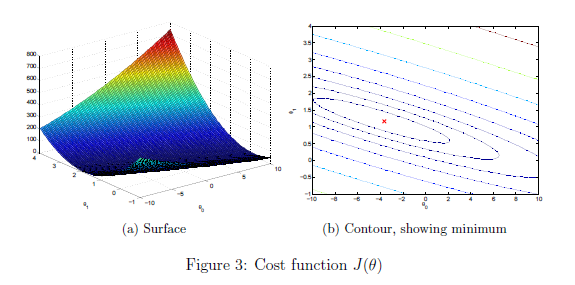

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

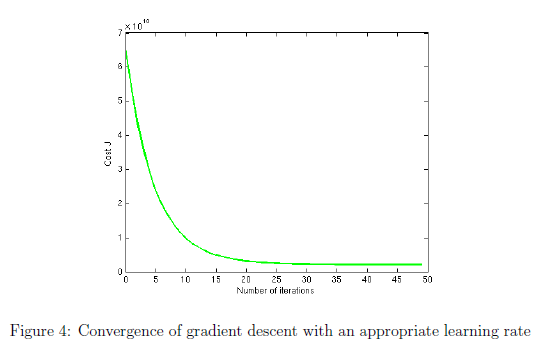

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 1;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

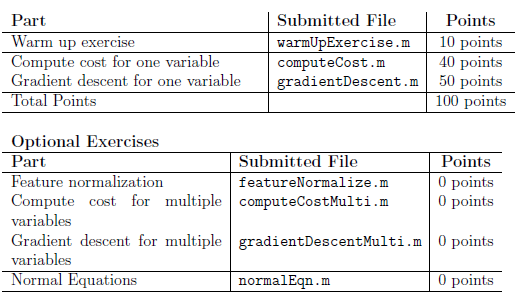

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.